## Sistema Ball & Beam

clear all;
close all;

format long g

Ts = 1e-3; %s

### Modelo do sistema

% Coeficientes modelo mola forte
coefA = [
         -1.97531085404608
         0.975319493951527
];

% A1 = - 1.595;
% A2 = 0.5946;
% A3 = -0.2822;

coefB = [
      2.59935147074799e-05
      1.72494796427973e-06
];

% B1 = 0;
% B2 = 0.0007851;
% B3 = 0.03867;

% Coeficientes modelo mola media
% coefA = [
%          -1.98459118905302
%          0.984594439497667
% ];
% 
% coefB = [
%       6.04195037933545e-05
%      -3.10626011333367e-05
% ];

A = [-1*coefA(1:end-1) eye(size(coefA, 1)-1); 
     -1*coefA(end, 1) zeros(1, size(coefA, 1)-1)]

A =           1.97531085404608                         1
        -0.975319493951527                         0



B = [coefB]

B =       2.59935147074799e-05
      1.72494796427973e-06


C = [1 zeros(1, size(A, 1)-1)]

C =      1     0


D = [0];
sysD = ss(A, B, C, D, 'Ts', Ts) 

sysD =
 
  A = 
            x1       x2
   x1    1.975        1
   x2  -0.9753        0
 
  B = 
              u1
   x1  2.599e-05
   x2  1.725e-06
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



A = sysD.A;
B = sysD.B;
C = sysD.C;
D = sysD.D;

### Modelo aumentado do sistema

A_a = [
    A zeros(size(A, 1), size(C, 1));
    -C eye(size(C, 1))
    ];
B_a = [B; zeros(1, size(B, 2))];
    
C_a = [C zeros(1, size(A_a, 1)-size(C, 2)); zeros(1, size(A_a, 1))];
% C_a = [C zeros(1, size(A_a, 1)-size(C, 2))];
sys_a = ss(A_a, B_a, C_a, D, Ts);

### Projeto do controlador Hinf

Acell{1} = sys_a.A;
Bcell{1} = sys_a.B;
Bw{1} = [1 zeros(1, size(A_a, 1)-1)]';
% Du = [0]';
Du = [0, 0.01]';
Dw = [0, 0]';
% Dw = [0]';

saturacao = 1024 / 1.255; % graus

[K,hinf,P] = hinf_discrete_sat_V2(Acell, Bcell, C_a, Du, Dw, Bw, saturacao);

MOSEK Version 10.1.10 (Build date: 2023-8-21 10:45:07)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 10              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 1 (scalarized: 45)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - prim

[K2,h2,P2] = h2_discrete(Acell, Bcell, C_a, Du, Dw, Bw, saturacao);

MOSEK Version 10.1.10 (Build date: 2023-8-21 10:45:07)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 10              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 3 (scalarized: 67)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - prim

Ganhos do controlador

disp(K')

         -24806.7827396954
         -24115.0964582193
          17.7886688200369



disp(K2')

         -12389.8120865688
          -10470.195703151
          139.424203030383



Autovalores da matriz P

disp(eig(P))

        0.0305148703689454
          30.2109284570298
          164203.243429405



disp(eig(P2))

          2.85828212191669
          506.756137948759
          90856.2258208678



Norma $H_{\infty }$

disp(hinf)

          335.410700798804



disp(h2)

           230.82997541403




K = K2;

### Ganhos

K_sys = [K(1:end-1)];
Ki = K(end);

### Amostragens

N = 1000;

### Constantes do filtro de Kalman

% covariância do ruído na equação   
Q = diag([0.8*10^-5 5*10^-5]);
% covariância do ruído na saída
R = diag(1*10^-5);                                       
U = eye(2);

w = repmat(sqrt(diag(Q)),1,N) .* randn(2,N);
v = repmat(sqrt(diag(R)),1,N) .* randn(1,N);

### Simulação

A = sysD.A;
B = sysD.B;
C = sysD.C;
D = sysD.D;

#### Condições iniciais

x_real{1} = [zeros(1, size(A, 1))]';
y_real(1) = C * x_real{1};
% x_ruido{1} = x_real{1} + U * w(:,1);
vi(1) = 0;

Estimadas

% x_priori{1} = [0 0]';
% x_hat{1} = [0 0]';
% y_hat(1) = C * x_hat{1};
% P_hat{1} = diag([0 0]);
% r = 0;

Simulação do sistema discreto

for k = 1:N 
    
    r(k) = 90 + 60 * sin(2*pi*k*1/1000);

    vi(k+1) = vi(k) + r(k) - y_real(k);
    u(k) = K_sys * x_real{k} + Ki * vi(k);

    % Saturar entrada    
    if u(k) >= saturacao
        u(k) = saturacao;
    end
    
    if u(k) <= -saturacao
        u(k) = -saturacao;
    end

    u(k) = u(k);

    % Sistema real
    if abs(u(k)) >= 650
        x_real{k+1} = A * x_real{k} + B *u(k);
        y_real(k+1) = C * x_real{k+1};
    else
        x_real{k+1} = A * x_real{k} + B * 0;
        y_real(k+1) = C * x_real{k+1};
    end
%     y_dot(k+1) = [0 1] * x_real{k+1};
% 
%     % Sistema com ruído
%     x_ruido{k+1} = A * x_real{k} + B * u(k) + U * w(:,k);
%     y_ruido(k+1) = C * x_real{k+1} + v(:, k);
%     y_dot_ruido(k+1) = [0 1] * x_real{k+1} + v(:,k);


end

### Gráficos

#### Esfera

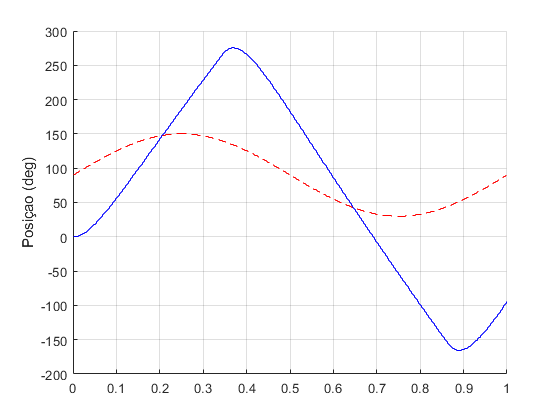

k = 1:N+1;

figure
% subplot(2,1,1)
hold on
stairs(k(1, 1:end-1)*Ts, y_real(1,1:end-1), 'b');
stairs(k(1, 1:end-1)*Ts, r, 'r--');
% stairs(k*Ts, y_hat, 'r');
% hold on
% stairs(k*Ts, y_ruido,'k:');
ylabel("Posiçao (deg)")
grid on
hold off

% 
% figure
% stairs(k*Ts, y_dot, 'b');
% hold on 
% % stairs(k*Ts, y_dot_ruido,'k:');
% hold on
% grid on
% legend("Velocidade real", "Velocidade com ruído", "Velocidade estimada");
% ylabel("Velocidade (cm/s)");
% xlabel("Tempo(s)");

#### Sinal de controle

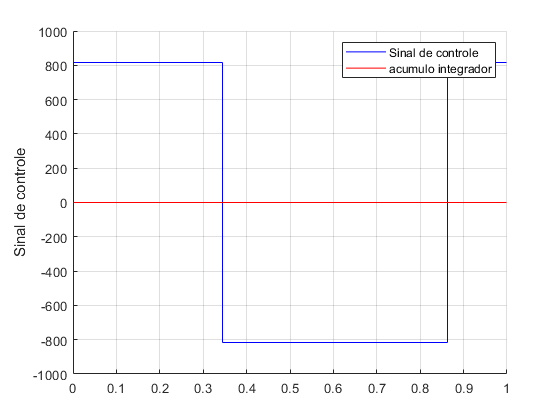

k = 1:N;

figure
hold on
stairs(k*Ts, u, 'b');
stairs(k*Ts, v, 'r');
ylabel("Sinal de controle")
legend("Sinal de controle", "acumulo integrador");
grid on
hold off